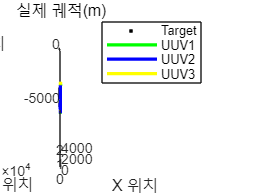

% trajectory 행렬 생성
time = 1000;
load("BadTrajec.mat");
load("CDN.mat");
True_Target = DOPgoodtrajectories1.target;
True_UUV1 = DOPgoodtrajectories1.torpedo1;
True_UUV2 = DOPgoodtrajectories1.torpedo2;
True_UUV3 = DOPgoodtrajectories1.mship;
Esti_Target_pos = zeros(time,6);
[Esti_Target_pos] = Esti_EKF(True_Target,True_UUV1,True_UUV2,True_UUV3,1,Esti_Target_pos,time);%, Esti_Target_pro

plot4line(True_Target,True_UUV1,True_UUV2,True_UUV3)

view([317 27])

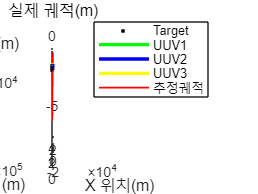

plot5line(True_Target,True_UUV1,True_UUV2,True_UUV3,Esti_Target_pos(:,1:3))
view([317 27])

%EKF
%MAIN EKF 
function [Esti_Target_pos] = Esti_EKF(Target,UUV1,UUV2,UUV3,condition,Esti_Target_pos,time)%, Esti_Target_pro
    %% EKF Setting
    Esti_P = eye(6); % 오차 공분산 행렬
    Q = eye(6)*0.0001; % 시스템 잡음 공분산 행렬
    sigma = deg2rad(1);
    R = (sigma^2) * eye(6);
    Esti_X = [20000; 1000; 0; 15*cos(-20)*cos(70); 15*sin(70); 15*sin(-20)];
    for i = 1 : time
        %R = eye(6)*condition(i,1);
        [Esti_X,Esti_P] = EKF(Esti_X,Esti_P,Q,R,Target(i,:)',UUV1(i,:)',UUV2(i,:)',UUV3(i,:)');
        Esti_Target_pos(i,:) = Esti_X;
        %Esti_Target_pro(i,:) = Esti_P;
    end

end


%EKF알고리즘
function [X,P] = EKF(X,P,Q,R,Target,UUV1,UUV2,UUV3)
    motion_model = [1 0 0 1 0 0; % model
                    0 1 0 0 1 0;
                    0 0 1 0 0 1;
                    0 0 0 1 0 0;
                    0 0 0 0 1 0;
                    0 0 0 0 0 1];
    % EKF돌리기
    %X = nextmotion_model(X,motion_model);
    X = motion_model * X;
    
    % 야코비안 계산4 * 6
    H = measurement_model(X, UUV1, UUV2,UUV3);
    
    % 오차 공분산 예측 6 *6
    P = prediction_step(P, Q);

    % 칼만 이득 계산
    K = P * H' * inv(H * P * H' + R);

    % 실제 경로의 상대 방위각 및 양각 정보(참값)
    z = h(Target, UUV1, UUV2, UUV3);

    % 참값에 노이즈 추가 -> 센서값
    z = z + [deg2rad(randn()); deg2rad(randn()); deg2rad(randn()); deg2rad(randn());deg2rad(randn()); deg2rad(randn())];
    
    % 비선형 측정 방정식 h(X)
    X = X + K * (z - h(X, UUV1, UUV2, UUV3));
    P = (eye(6) - K * H) * P;
end

% measurement_model
function H = measurement_model(target_state, torpedo1_state, torpedo2_state,mship_state)
    dx1 = target_state(1) - torpedo1_state(1);
    dy1 = target_state(2) - torpedo1_state(2);
    dz1 = target_state(3) - torpedo1_state(3);
    dx2 = target_state(1) - torpedo2_state(1);
    dy2 = target_state(2) - torpedo2_state(2);
    dz2 = target_state(3) - torpedo2_state(3);
    dx3 = target_state(1) - mship_state(1);
    dy3 = target_state(2) - mship_state(2);
    dz3 = target_state(3) - mship_state(3);

    % q1, q2는 거리 제곱합
    q1 = dx1^2 + dy1^2 + dz1^2;
    q2 = dx2^2 + dy2^2 + dz2^2;
    q3 = dx3^2 + dy3^2 + dz3^2;

    % 방위각 및 양각에 대한 편미분 계산
    H_bearing1 = [-dy1/q1, dx1/q1, 0, 0, 0, 0];
    H_elevation1 = [-dx1*dz1/(q1*sqrt(dx1^2 + dy1^2)), -dy1*dz1/(q1*sqrt(dx1^2 + dy1^2)), sqrt(dx1^2 + dy1^2)/q1, 0, 0, 0];
    
    H_bearing2 = [-dy2/q2, dx2/q2, 0, 0, 0, 0];
    H_elevation2 = [-dx2*dz2/(q2*sqrt(dx2^2 + dy2^2)), -dy2*dz2/(q2*sqrt(dx2^2 + dy2^2)), sqrt(dx2^2 + dy2^2)/q2, 0, 0, 0];
    
    H_bearing3 = [-dy3/q3, dx3/q3, 0, 0, 0, 0];
    H_elevation3 = [-dx3*dz3/(q3*sqrt(dx3^2 + dy3^2)), -dy3*dz2/(q3*sqrt(dx3^2 + dy3^2)), sqrt(dx3^2 + dy3^2)/q3, 0, 0, 0];

    % 최종 H 행렬
    H = [H_bearing1;
         H_elevation1;
         H_bearing2;
         H_elevation2;
         H_bearing3;
         H_elevation3;
         ];
end

% 타겟의 XYZ 위치 정보를 베어링 및 양각 정보로 변환(센서 데이터화)
function z = h(target_state, torpedo1_state, torpedo2_state,mship_state)
    dx1 = target_state(1) - torpedo1_state(1);
    dy1 = target_state(2) - torpedo1_state(2);
    dz1 = target_state(3) - torpedo1_state(3);
    dx2 = target_state(1) - torpedo2_state(1);
    dy2 = target_state(2) - torpedo2_state(2);
    dz2 = target_state(3) - torpedo2_state(3);
    dx3 = target_state(1) - mship_state(1);
    dy3 = target_state(2) - mship_state(2);
    dz3 = target_state(3) - mship_state(3);

    % 방위각 및 양각 계산
    bearing1 = atan2(dy1, dx1);
    elevation1 = atan(dz1 / sqrt(dx1^2 + dy1^2));
    
    bearing2 = atan2(dy2, dx2);
    elevation2 = atan(dz2 / sqrt(dx2^2 + dy2^2));

    bearing3 = atan2(dy3, dx3);
    elevation3 = atan(dz3 / sqrt(dx3^2 + dy3^2));

    % z는 방위각과 양각을 포함
    z = [bearing1; elevation1; bearing2; elevation2; bearing3; elevation3];
end

% P_prediction
function P = prediction_step(P, Q)
    H = [1 0 0 1 0 0;
         0 1 0 0 1 0;
         0 0 1 0 0 1;
         0 0 0 1 0 0;
         0 0 0 0 1 0;
         0 0 0 0 0 1];
    P = H * P * H' + Q;
end

궤적및 그래프 그리는 함수


%Target UUV1 UUV2 실제 궤적 그리기
function UUV123Target = plot5line(Target,UUV1,UUV2,UUV3,Esti_Tar)
    figure;
    plot3(Target(:, 1), Target(:, 2),Target(:,3), 'k.', 'LineWidth', 2); hold on;
    plot3(UUV1(:, 1), UUV1(:, 2),UUV1(:, 3), 'g-', 'LineWidth', 2);
    plot3(UUV2(:, 1), UUV2(:, 2),UUV2(:, 3), 'b-', 'LineWidth', 2);
    plot3(UUV3(:, 1), UUV3(:, 2),UUV3(:, 3), '-y', 'LineWidth', 2);
    plot3(Esti_Tar(:, 1), Esti_Tar(:, 2),Esti_Tar(:, 3), 'r-', 'LineWidth', 1);

    xlabel('X 위치(m)');
    ylabel('Y 위치(m)');
    zlabel('Z 위치(m)');
    title('실제 궤적(m)'); 
    legend('Target', 'UUV1', 'UUV2','UUV3','추정궤적');
end

%P파라미터 그래프 그리기
% function P_para = plotP(Esti_P)
%     figure;
%     plot(Esti_P);
%     xlabel('time');
%     ylabel('P(파라미터)');
%     title('EKF P 파라미터 추이');
% end

%Esti_Target Target UUV1 UUV2 실제 궤적 그리기
function RealTrajec = plot4line(Target,UUV1,UUV2,UUV3)
    figure;
    plot3(Target(:, 1), Target(:, 2),Target(:,3), 'k.', 'LineWidth', 2); hold on;
    plot3(UUV1(:, 1), UUV1(:, 2),UUV1(:, 3), 'g-', 'LineWidth', 2);
    plot3(UUV2(:, 1), UUV2(:, 2),UUV2(:, 3), 'b-', 'LineWidth', 2);
    plot3(UUV3(:, 1), UUV3(:, 2),UUV3(:,3), '-y', 'LineWidth', 2);

    xlabel('X 위치');
    ylabel('Y 위치');
    zlabel('Z 위치')
    title('실제 궤적(m)'); 
    legend('Target', 'UUV1', 'UUV2','UUV3');
end
